syms x y th alpha dx dy dth ddx ddy ddth F 'real'
syms mass width height g inertia offset a aN temp 'real'

q = [x; y; th];
dq = [dx; dy; dth];
ddq = [ddx; ddy; ddth];

### Defining positions, velocities, energies

% position and velocity
pBody = [x;
         y];

vBody = jacobian(pBody, q) * dq;

% potential energy
Ttot = 0.5*mass*transpose(vBody)*vBody ...
    + 0.5*inertia*(dth)^2;
Ttot = simplify(Ttot)

$$Ttot = \frac{\mathrm{inertia}\,{\mathrm{dth}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dx}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dy}}^{2}}{2}$$


% kinetic energy
Vtot = mass*[0 g]*pBody

$$Vtot = g\,\mathrm{mass}\,y$$

### Manipulator equation terms

M = simplify(hessian(Ttot, dq));

dM = sym(zeros(size(M)));
for i = 1:size(dM, 1)
    for j = 1:size(dM, 2)
        dM(i,j) = jacobian(M(i,j), q) * dq;
    end
    
end
dM = simplify(dM);

C = dM*dq - transpose(jacobian(Ttot, q));
C = simplify(C);

G = simplify(jacobian(Vtot, q)');

### Q input matrix

% rotation matrix
R = [  sin(th) cos(th)
      -cos(th)  sin(th)];
 
% location of the input force
r = [x; y] + R * [width/2; 0]

$$r = \left(\begin{array}{c} x+\frac{\mathrm{width}\,\sin\left(\mathrm{th}\right)}{2}\\ y-\frac{\mathrm{width}\,\cos\left(\mathrm{th}\right)}{2} \end{array}\right)$$


% rotation matrix for force
Rf = [ cos(th + alpha)  -sin(th + alpha)
      sin(th + alpha)   cos(th + alpha)];
  
% input force with respect to inertia
f = Rf * [0; F]

$$f = \left(\begin{array}{c} -F\,\sin\left(\alpha +\mathrm{th}\right)\\ F\,\cos\left(\alpha +\mathrm{th}\right) \end{array}\right)$$


% partial derivatives
Q = simplify(f' * jacobian(r, q))';

% calculate B matrix
B = jacobian(Q, [F; alpha]);

### Linearise the model

u = [F; alpha];

% the backslash operator \ solves the equation Ax = b
% more efficienctly than x = inv(A) * b
acceleration_eqns = simplify(M \ (-C - G + B*u))

$$acceleration\_eqns = \left(\begin{array}{c} -\frac{F\,\left(\sin\left(\alpha +\mathrm{th}\right)+\alpha \,\cos\left(\alpha +\mathrm{th}\right)\right)}{\mathrm{mass}}\\ -\frac{g\,\mathrm{mass}-F\,\cos\left(\alpha +\mathrm{th}\right)+F\,\alpha \,\sin\left(\alpha +\mathrm{th}\right)}{\mathrm{mass}}\\ -\frac{F\,\mathrm{width}\,\left(\sin\left(\alpha \right)+\alpha \,\cos\left(\alpha \right)\right)}{2\,\mathrm{inertia}} \end{array}\right)$$

dyn = [acceleration_eqns; dq];

% Jacobian of dynamics, with the operating point subbed in
A = jacobian(dyn, [dq.', q.']);
A = subs(A, [dq.', q.', u.'], [0,0,0,0,0,0,mass*g,300]);

B = jacobian(dyn, [u.']);
B = subs(B, [dq.',q.',u.'],[0,0,0,0,0,0,mass*g,470]);

Substitue in specific parameters

% Params needed for simulation
m_ = 1000;
w_ = 5;
h_ = 15;
offset_ = 4;
I_ = ((1/12 * m_) * (w_^2 + h_^2)) + (m_ * offset_^2);
g_ = 9.81;

% Subsitute to get numerical A and B
A = double(subs(A, [mass,width,inertia,g], [m_,w_,I_,g_]));
B = double(subs(B, [mass,width,inertia,g], [m_,w_,I_,g_]));

C = eye(6);

D = [];

states = {'dx' 'dy' 'dth' 'x' 'y' 'th'};
inputs = {'u1' 'u2'};
outputs = {'dx' 'dy' 'dth' 'x' 'y' 'th'};

sys_ss = ss(A, B, C, D, 'statename', states,...
                        'inputname', inputs,...
                        'outputname', outputs)

sys_ss =
 
  A = 
           dx     dy
   dx       0      0
   dy       0      0
   dth      0      0
   x        1      0
   y        0      1
   th       0      0
 
          dth      x
   dx       0      0
   dy       0      0
   dth      0      0
   x        0      0
   y        0      0
   th       1      0
 
            y     th
   dx       0  -2942
   dy       0  74.84
   dth      0      0
   x        0      0
   y        0      0
   th       0      0
 
  B = 
              u1        u2
   dx    -0.1522     -4365
   dy     0.4447     -1484
   dth  -0.01033    -296.3
   x           0         0
   y           0         0
   th          0         0
 
  C = 
         dx   dy  dth
   dx     1    0    0
   dy     0    1    0
   dth    0    0    1
   x      0    0    0
   y      0    0    0
   th     0    0    0
 
          x    y   th
   dx     0    0    0
   dy     0    0    0
   dth    0    0    0
   x      1    0    0
   y      0    1    0
   th     0    0    1
 
  D = 
        u1 

### LQR - Linear Quadratic Regulator

Stabilises states!

Q = eye(6);
Q(4,4) = 500;
Q(5,5) = 500;
Q(6,6) = 500;
R = eye(2);

% calculate LQR gain

K = lqr(A, B, Q, R)

K = 	1.0e+03 *

    0.0003    0.0095   -0.0515    0.0003    0.0224   -0.1199
    0.0042    0.0000   -0.0780    0.0224   -0.0003   -1.1006


Find the closed loop system

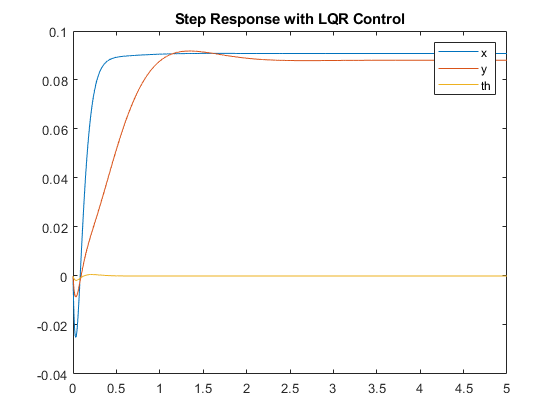

Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];

sys_cl = ss(Ac, Bc, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);
t = 0:0.001:5;
r = 2*ones(length(t), 2);
[y,t,x] = lsim(sys_cl, r, t);

% plot the position states
plot(t, y(:, 4:6));
legend(["x"; "y"; "th"]);
title('Step Response with LQR Control')

## Intercept a moving target

u = [F; alpha];
dyn = [acceleration_eqns(3); dth];
dyn = subs(dyn, [mass,width,inertia,g], [m_,w_,I_,g_])

$$dyn = \left(\begin{array}{c} -\frac{171798691840\,F\,\left(\sin\left(\alpha \right)+\alpha \,\cos\left(\alpha \right)\right)}{2531167393109333}\\ \mathrm{dth} \end{array}\right)$$



% OUTPUTS are acceleration: ddx, ddy
Y = subs(acceleration_eqns(1:2), [mass,width,inertia,g], [m_,w_,I_,g_])

$$Y = \left(\begin{array}{c} -\frac{F\,\left(\sin\left(\alpha +\mathrm{th}\right)+\alpha \,\cos\left(\alpha +\mathrm{th}\right)\right)}{1000}\\ \frac{F\,\cos\left(\alpha +\mathrm{th}\right)}{1000}-\frac{F\,\alpha \,\sin\left(\alpha +\mathrm{th}\right)}{1000}-\frac{981}{100} \end{array}\right)$$

Find A, B, C, D for state space equations:

mass = 1000;
g = 9.8;

A = jacobian(dyn, [dth, th]);
A = subs(A,[dth, th, u.'],[0,0,mass*g,300]);

B = jacobian(dyn, [u.']);
B = subs(B,[dth, th, u.'],[0,0,mass*g,470]);

% this time we need to linearise the output equation
C = jacobian(Y, [dth, th]);
C = subs(C,[dth, th, u.'],[0,0,mass*g,0]);

% and linearise feedforward
D = jacobian(Y, [u.']);
D = subs(D,[dth, th, u.'],[0,0,mass*g,0]);

Next, we augment the Jacobian with integral states for accelerations

mass = 1000;
g = 9.8;

newA = [0, -g, 0, 0;...
        0,  0, 0, 0];
tempA = horzcat(A, zeros(2,2));

% New A Matrix
A_aug = vertcat(tempA, newA);

% New B Matrix
B_aug = vertcat(B, D);

% New C Matrix
newC = [0, 0, 0, 0;...
        0, 0, 0, 0];
tempC = horzcat(C,zeros(2,2));
C_aug = vertcat(tempC, newC);

% New D Matrix - STAYS THE SAME
D_aug = vertcat(D, zeros(2,2));

% get numerical versions (right now they're symbolic)
A = double(A_aug);
B = double(B_aug);
C = double(C_aug);
D = double(D_aug);

% linearized system
states = {'dth' 'th' 'ddxE' 'ddyE'};
inputs = {'u1' 'u2'};
outputs = {'ddx' 'ddy' 'ddxE' 'ddyE'};

sys_ss = ss(A, B, C, D, 'statename', states,...
                        'inputname', inputs,...
                        'outputname', outputs)

sys_ss =
 
  A = 
          dth    th  ddxE
   dth      0     0     0
   th       1     0     0
   ddxE     0  -9.8     0
   ddyE     0     0     0
 
         ddyE
   dth      0
   th       0
   ddxE     0
   ddyE     0
 
  B = 
               u1        u2
   dth   -0.01033      -296
   th           0         0
   ddxE         0     -19.6
   ddyE     0.001         0
 
  C = 
          dth    th  ddxE
   ddx      0  -9.8     0
   ddy      0     0     0
   ddxE     0     0     0
   ddyE     0     0     0
 
         ddyE
   ddx      0
   ddy      0
   ddxE     0
   ddyE     0
 
  D = 
            u1     u2
   ddx       0  -19.6
   ddy   0.001      0
   ddxE      0      0
   ddyE      0      0
 
Continuous-time state-space model.



Finally - let's test the linearized version of the rocket model

% LQR - regulator/stabilising states
Q = eye(4);
Q(3,3) = 200;
Q(4,4) = 200;
R = eye(2);

% calculate LQR gain
K = lqr(A, B, Q, R)

K =    -0.0018   -0.0238    0.0258   14.1421
   -2.3683  -25.6409   14.1421   -0.0258


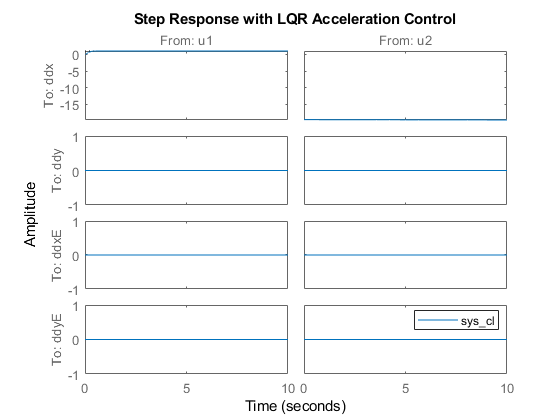


% closed loop
Ac = [(A-B*K)];
Br = [0 0; 0 0; -1 0; 0 -1];
Cc = [C];
Dc = [D];

sys_cl = ss(Ac, Br, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);

t = 0:0.001:10;
step(sys_cl, t)
legend
title('Step Response with LQR Acceleration Control')